# Demo for Interporlation of corr. matrices

Multivariate Simulation Using A Locally Varying Coregionalization Model

Alvaro I. Riquelme and Julian M. Ortiz

*alvaro.riquelme@queensu.ca*

## Import data

clc
clear
addpath(genpath('./DTI_SpectralQuaternion'));
addpath(genpath('./covariancetoolbox'));


db=dlmread('myData.txt',',',1,0);

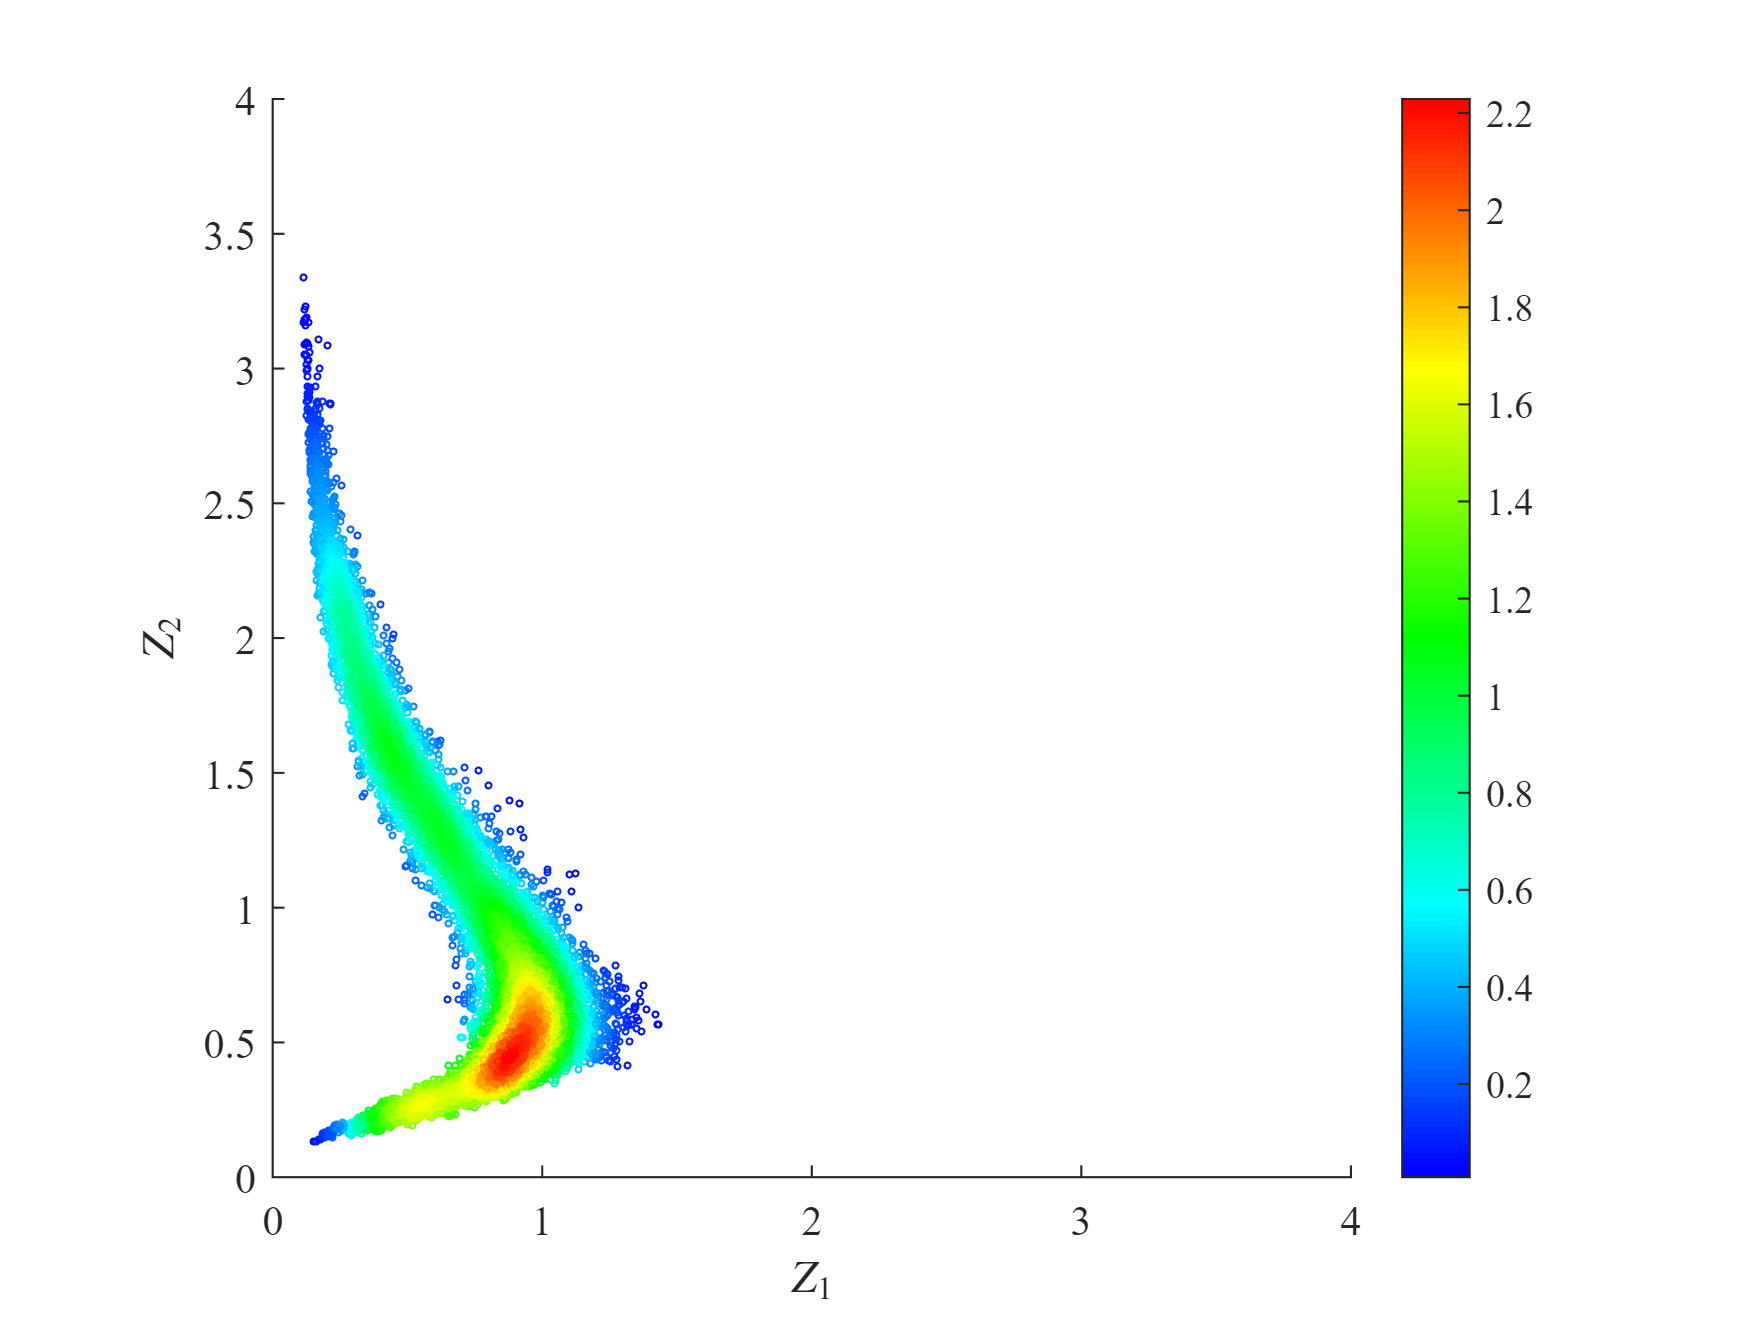

% scatter plot
figure
cs=hsv;
cs=(cs(1:172,:));
scatter(db(:,4),db(:,5),2,mvksdensity([db(:,4) db(:,5)],[db(:,4) db(:,5)]))
xlim([0 4])
ylim([0 4])
xlabel('$Z_1$','interpreter','latex')
ylabel('$Z_2$','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
pbaspect([1 1 1])

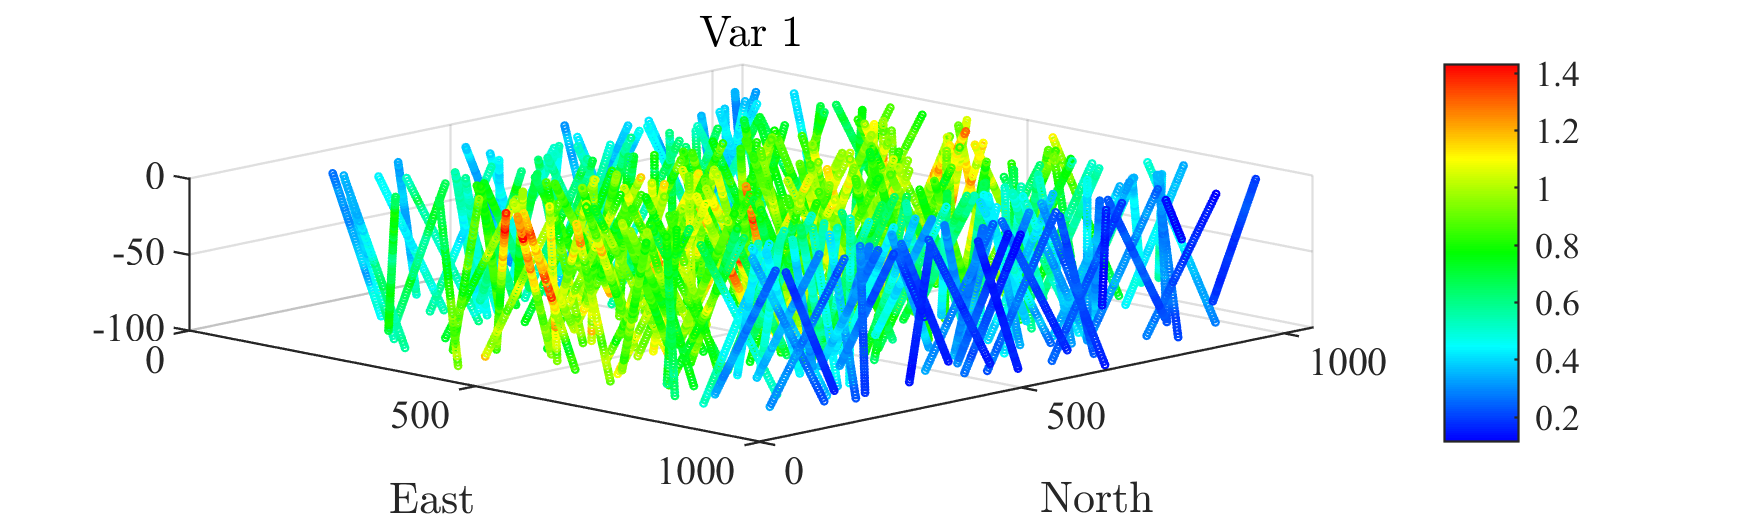

%locmap Var_2
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,db(:,4))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('Var 1','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
view([44.1 46.5])

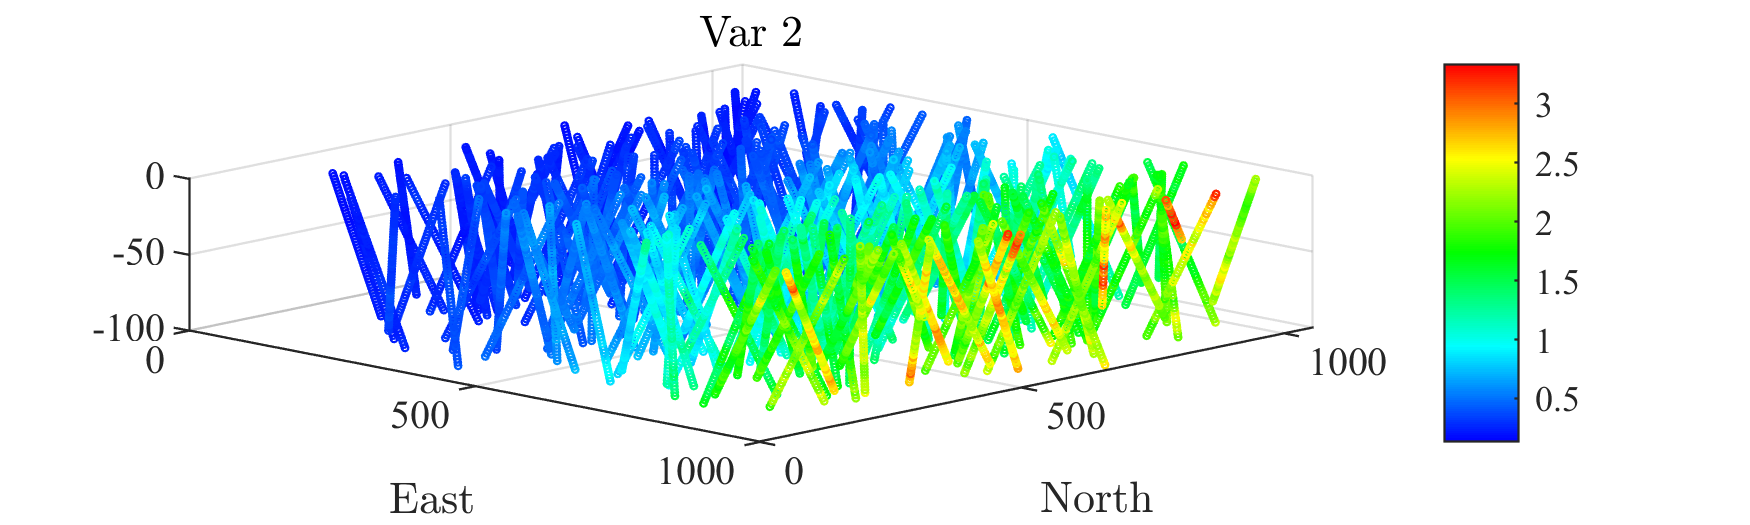

%locmap Var_2
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,db(:,5))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('Var 2','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
view([44.1 46.5])

## Inference of local correlation

[COV,g_db] = Local_corr(db(:,1:3),db(:,4:5),100);

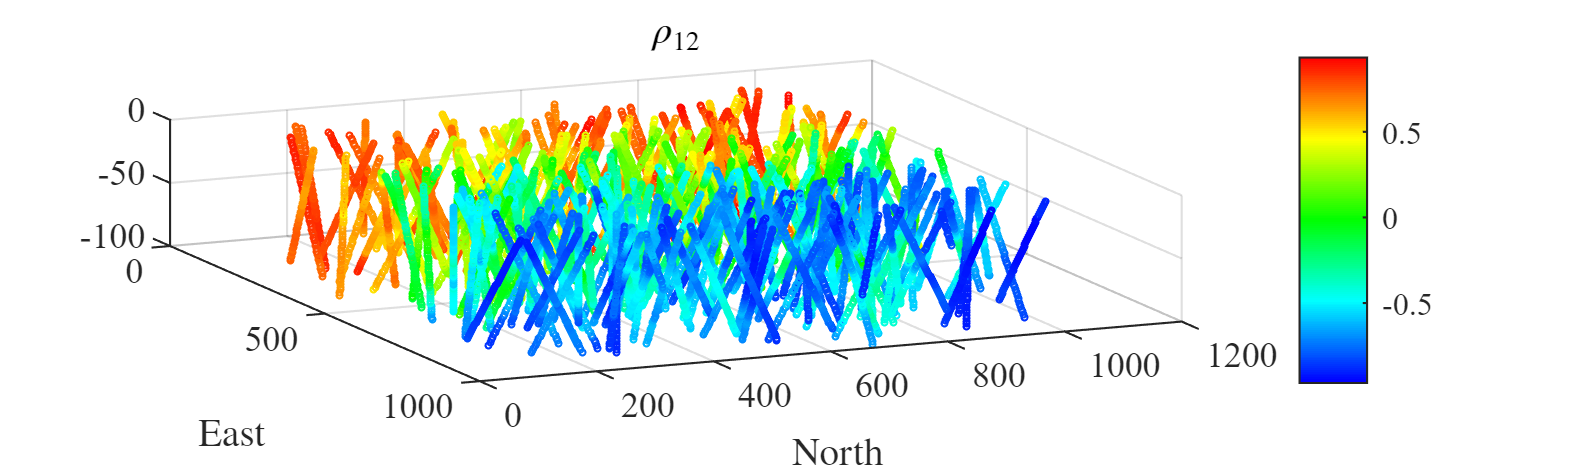

%locmap COV(1,2)
figure( 'Position', [30 30 500 150]);
cs=hsv;
cs=(cs(1:172,:));
scatter3(db(:,1),db(:,2),db(:,3),2,squeeze(COV(1,2,:)))
xlabel('East','interpreter','latex')
ylabel('North','interpreter','latex')
title('$\rho_{12}$','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
view([66.2 49.5])

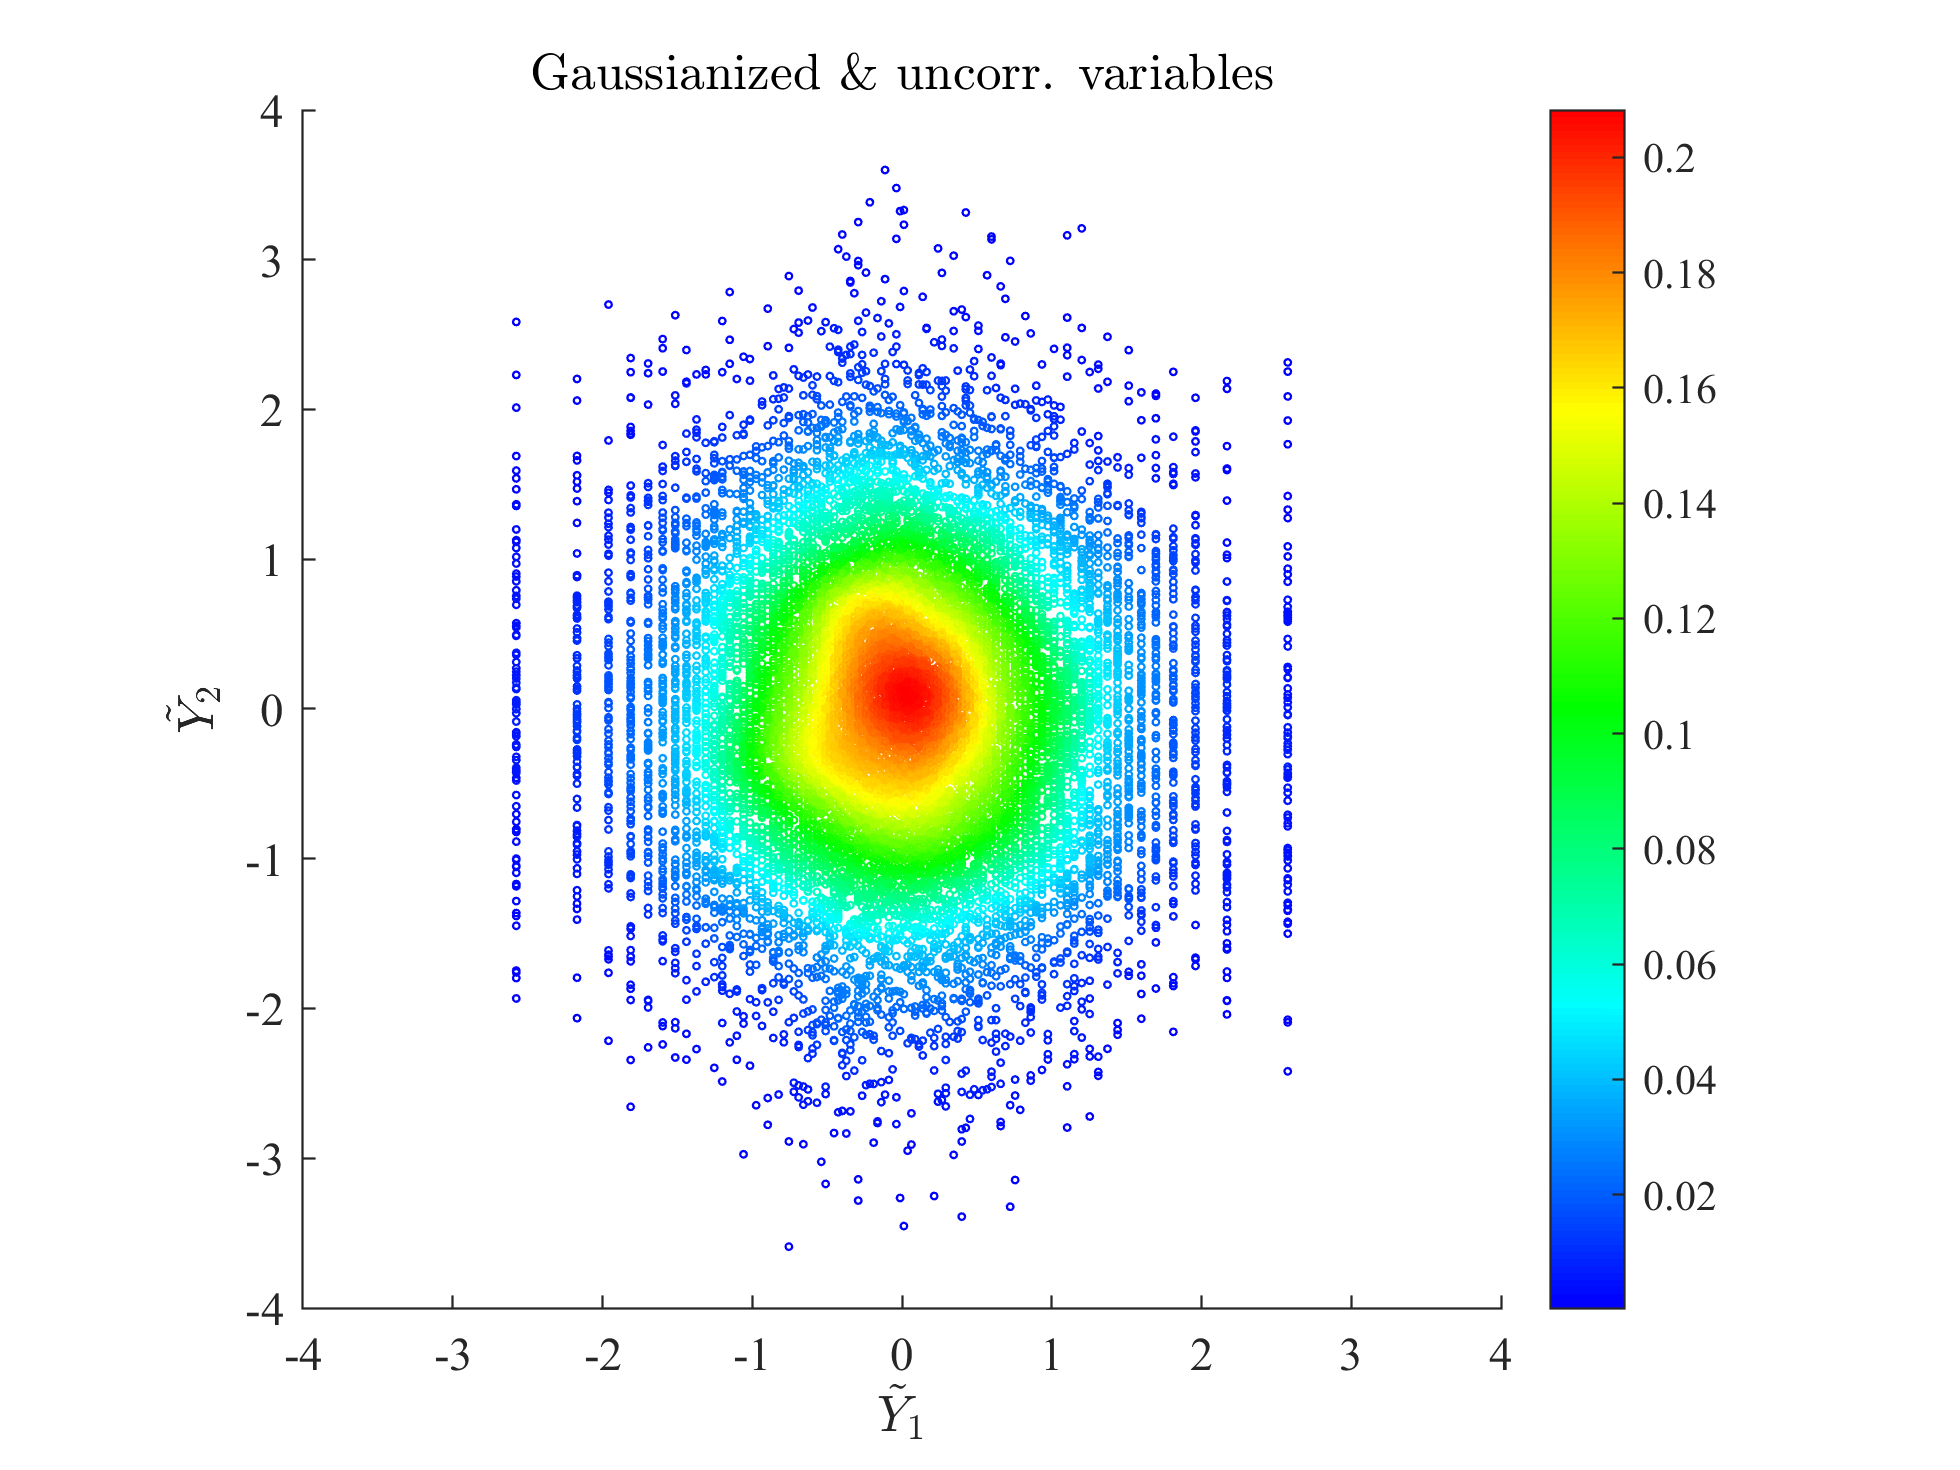

% scatter plot gassianized variables
figure
cs=hsv;
cs=(cs(1:172,:));
scatter(g_db(:,1),g_db(:,2),2,mvksdensity([g_db(:,1) g_db(:,2)],[g_db(:,1) g_db(:,2)]))
xlim([-4 4])
ylim([-4 4])
xlabel('$\tilde{Y}_1$','interpreter','latex')
ylabel('$\tilde{Y}_2$','interpreter','latex')
title('Gaussianized \& uncorr. variables','interpreter','latex')
set(gca,'fontname','times')
colorbar
colormap(flipud(cs))
pbaspect([1 1 1])

## Create interpolation grid

N=10;

LimX=1000;

x=linspace(0,LimX,N);
y=linspace(0,LimX,N);

[X,Y]=meshgrid(x,y);

grid = [X(:) Y(:) Y(:).*0-50]; % set elevation at -50

N_grid = size(grid,1);

## Determine interpolation weights based on distance from grid points to samples

A = grid;
B = db(:,1:3);

% set exponential decay weight
D = exp(-pdist2(A,B)/1000);

positions=zeros(size(grid,1),51);
weights=zeros(size(grid,1),51);

%run for grid location, pick closes 50 samples
for i=1:size(grid,1)
    [weights_samp, index]=sort(D(i,:),'descend');
    positions(i,1) = i;
    positions(i,2:end) = index(1:50);
    weights(i,1) = i;
    weights(i,2:end) = weights_samp(1:50);
end

lambdas = weights;
%normalize weights to sum 1
lambdas(:,2:end) = weights(:,2:end)./sum(weights(:,2:end),2);

### Run Correlation Interpolation

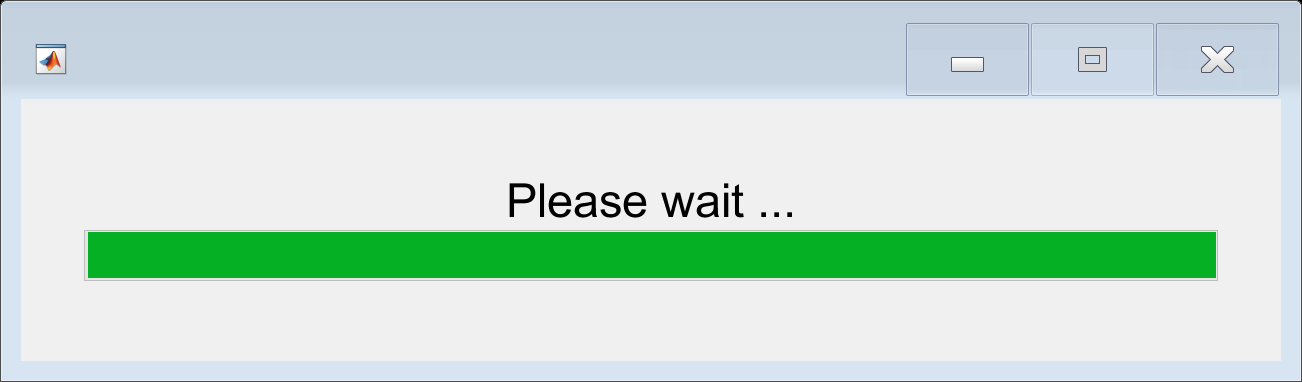

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


CorrM=parforWaitbar(COV,positions,lambdas,N_grid);

### Plot interpolated corr matrices on grid

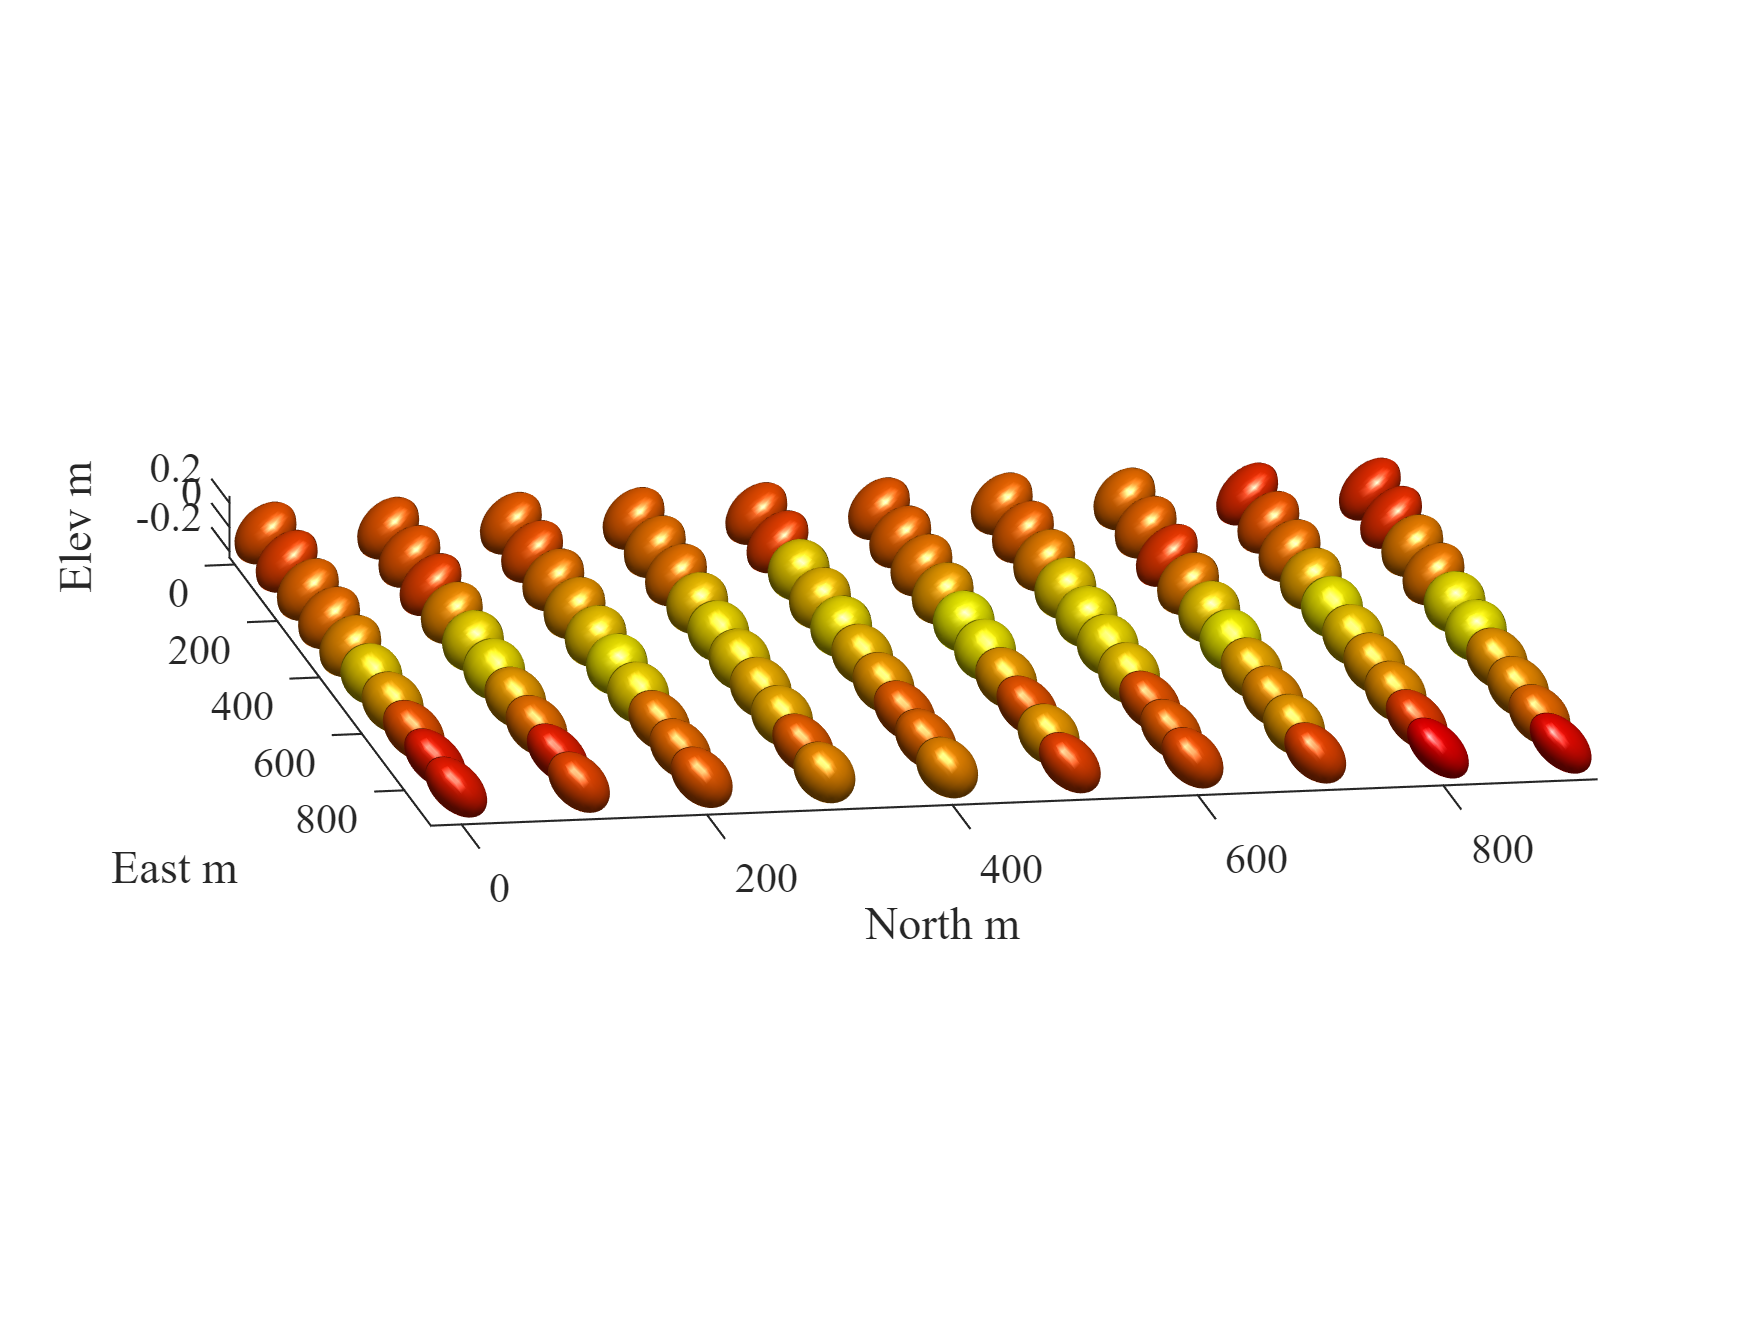

S1 = difftensor;
k=0;
elem=1:N_grid;

for ii = 1 : 10
    for jj = 1:10
        k = ii + N*(jj-1);
        S1(ii,jj) = [1 0 0;[[0 ; 0] CorrM(:,:,k)]]; %enlarge for visualization
    end
end

graph_display(S1,0.5,'Hacol')
view([80.2 13.3])
xlabel('East m')
ylabel('North m')
zlabel('Elev m')
xticklabels({'0','200','400','600','800'})
yticklabels({'0','200','400','600','800'})
set(gca,'fontname','times')

## MATLAB Functions

function [COV,g_db] = Local_corr(coorinates,variables,neigh_size)


x = coorinates(:,1:3)';
diagon=sum(x.*x,1);

% save entry number of upper triangular part of correlation matrix
index=(triu(ones(2)))>0;
index=index(:);

%run for each sample
for i=1:size(variables,1)

    %create local database
    db_dum=[];
    %compute distance matrix among samples and pick closest neigh_size
    IP = sum(x(:,i).* x,1);
    [dist, clo]=sort(sqrt(diagon+(diagon*0+IP(1,i))-2*IP));
    db_dum=variables(clo(1:neigh_size),:);

    m=1;
    for j=1:size(variables,2)
        % Run anamorphosis for variable j
        prob=1/neigh_size*ones(neigh_size,1);
        [~,c]=sort(db_dum(:,j));
        m=find(c==m);
        cdf=cumsum(prob);
        gslib_cdf=cdf-(1/neigh_size*ones(neigh_size,1)/2);
        x_ni=norminv(gslib_cdf);
        db_dum=[db_dum(c,:) x_ni];
    end
    db_gs=db_dum(:,size(variables,2)+1:end);
    %compute corr matrix and save
    corr_m=corr(db_gs);
    COV(:,:,i)=corr_m;

    c=chol(corr_m)';
    c_inv=c^-1;
    
    %save gaussianized database
    g_db(i,:)=c_inv*db_gs(m,:)';
end

end

function [CorrM] = parforWaitbar(COV,positions,lambdas,N_grid)
%% Multicore correlation interpolation

CorrM(:,:,N_grid)=eye(size(COV(:,:,1)));

D = parallel.pool.DataQueue;
h = waitbar(0, 'Please wait ...');
afterEach(D, @nUpdateWaitbar);
p = 1;
parfor i= 1 : N_grid
    CorrM(:,:,i)=cwmean(COV(:,:,positions(i,2:end)),lambdas(i,2:end)');
    send(D, i); 
end

function nUpdateWaitbar(~)
    waitbar(p/(N_grid), h);
    p = p + 1;
end

end


function [CorrM]= cwmean(Lt,w)
            COV=Lt;
            N_itermax = 20;
            N_itermax_D = 20;
            tol = 10^-5;

            A = eye(size(COV,1));
            niter = 0;
            fc = 0;

            del=0.05;

            while (niter<N_itermax)
                niter = niter+1;

                NTrial = size(COV,3);
                N_elec = size(COV,1);

                for n = 1:NTrial
                    D_t=eye(N_elec);
                    niterD=0;
                    while (niterD<N_itermax_D) %% optimization on the fiber
                        niterD = niterD+1;
                        dum=D_t*logm(COV(:,:,n)*D_t*A^-1*D_t);
                        Tri=eye(N_elec).*(dum+dum');
                        D_t=D_t*expm(-del*D_t^-1*Tri);
                    end
                    Ct_t(:,:,n)=D_t*COV(:,:,n)*D_t;
                end

                % Tangent space mapping
                T = Tangent_space(Ct_t,A);
                % sum of the squared distance
                fcn = sum(sum(T.^2));
                % improvement
                conv = abs((fcn-fc)/fc);
                if conv<tol % break if the improvement is below the tolerance
                   break; 
                end
                % arithmetic mean in tangent space
                TA = mean(T.*w',2);
                % back to the manifold
                A = UnTangent_space(TA,A);
                % back to Corr(n)
                if ~issymmetric(A)
                     A=(A+A')/2;
                end
                A = diag(diag(A))^-0.5*A*diag(diag(A))^-0.5;
                fc = fcn;
            end
            
            CorrM = A;
end